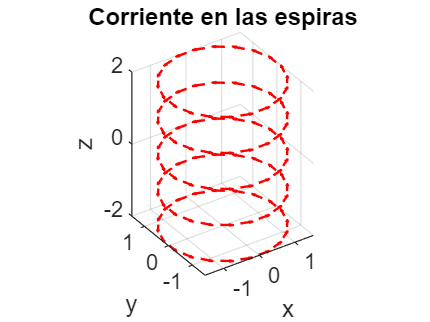

% -------------------- PARTE 1: GRAFICACIÓN DE LAS ESPIRAS --------------------
nl = 5; % Número de espiras
N = 20; % Puntos por espira
R = 1.5; % Radio de cada espira
sz = 1; % Separación entre espiras (paso en Z)
I = 300; % Corriente (A)
mo = 4*pi*1e-7; % Permeabilidad magnética del vacío
km = mo * I / (4*pi); % Constante de Biot–Savart
rw = 0.2; % Grosor efectivo del alambre

%{
Las primeras líneas del código son la inicialización de valores, se
establece las dimenciones de las espiras
%}

% Espiras centradas en Z
dtheta = 2*pi / N;
ang = 0:dtheta:(2*pi - dtheta);
s = 1;

%{
La siguiente parte es crear un vector de angulos, que se usara para
graficar cada circulo, con 20 secciones que grafican desde 0 hasta 2pi rad
%}

for i = 1:nl
    Px(s:s+N-1) = R * cos(ang);
    Py(s:s+N-1) = R * sin(ang);
    Pz(s:s+N-1) = -(nl-1)/2*sz + (i-1)*sz;
    dx(s:s+N-1) = -Py(s:s+N-1) * dtheta;
    dy(s:s+N-1) = Px(s:s+N-1) * dtheta;
    s = s + N;
end

dz = zeros(1, N*nl);

%{
Este for-loop genera vectores con los puntos en x (Px), y (Py), z (Pz) que
se necesitan para graficar punto por punto (tomando en cuenta las 20
divisiones hechas) y se repite 5 veces (la cantidad de espiras
establecidas para la simulación)
Para encontrar la dirección de la corriente se busca la tangente al punto,
esta es encontrada con la derivada de los puntos y es guardada en dx y dy
Para calcular esta tangente se usa la derivada de los puntos polares:
(−Rsinθ,Rcosθ), que es lo mismo que (-y,x), y se multiplica por el angulo
para darle una longitud
Como la corriente no se mueve en z, se llena de 0s en dz
%}

figure(1)
quiver3(Px, Py, Pz, dx, dy, dz, 0.5, '-r', 'LineWidth', 1);
view(-34, 33);
title('Corriente en las espiras');
xlabel('x'); 
ylabel('y'); 
zlabel('z');
axis equal

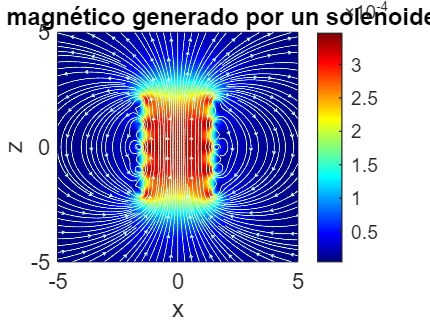


%{
Graficar los vectores calulados en el for-loop
%}

% -------------------- PARTE 2: CÁLCULO DEL CAMPO MAGNÉTICO --------------------
%Uso de la Ley de Biot-Savart
ds = 0.1;
z = -5:ds:5;
x = -5:ds:5;
y = -5:ds:5;
Lx = length(x); Ly = length(y); Lz = length(z);
dbx = zeros(Lx, Ly, Lz,'single');
dby = zeros(Lx, Ly, Lz,'single');
dbz = zeros(Lx, Ly, Lz,'single');

%{
Establecemos el "área de trabajo" (meshgrid), donde se calculará la aportación
en el campo magnético de las espiras cargadas eléctricamente 
Luego se cálcula la cantidad de puntos que habrá eb dicha área de trabajo y
se guarda en las variables Lx, Ly, y Lz
Después se crean matrices para guardar los componentes x, y, z del campo 
magnético (dbx, dby y dbz)
%}

for i = 1:Lx
    for j = 1:Ly
        for k = 1:Lz
            for l = 1:nl*N
                rx = x(i) - Px(l);
                ry = y(j) - Py(l);
                rz = z(k) - Pz(l);
                r = sqrt(rx^2 + ry^2 + rz^2 + rw^2);
                r3 = r^3;
                dbx(i,j,k) = dbx(i,j,k) + km * dy(l) * rz / r3;
                dby(i,j,k) = dby(i,j,k) + km * dx(l) * rz / r3;
                dbz(i,j,k) = dbz(i,j,k) + km * (dx(l) * ry - dy(l) * rx) / r3;
            end
        end
    end
end

%{
Se crean for-loops anidados para recorrer cada punto de la malla (x,y,z) en cada
punto de cada espira, es decir, recorre todos los puntos fuente
Dentro del for l = 1:nl*N e calcula el desplazamiento/distancia entre el
punto de la malla y el punto fuente, separado entre los componentes x,y,z,
lo que quiere decir que analiza individualmente estas aportaciones, y luego
cálcula la magnitud de la distancia (r) --> rw es un valor de corrección
para evitar tener 0
Finalmente cálcula el campo magnético en cada punto de la malla causado por
cada punto fuente usando la Ley de Biot-Savart (aquí es donde se empiezan a
llenar las matrices dbx, dby y dbz
%}

% -------------------- PARTE 3: Visualización --------------------
centery = round(Ly/2); % Definir el índice en Y para visualizar el plano central
%{
Es decir, aproxima donde esta el centro del eje y para ver el "corte" y
observar las contribuciones en el plano xz
%}

Bx_xz = squeeze(dbx(:, centery, :)); % Extraer la componente Bx en el plano XZ
Bz_xz = squeeze(dbz(:, centery, :)); % Extraer la componente Bz en el plano XZ
Bxz = sqrt(Bx_xz.^2 + Bz_xz.^2); % Magnitud del campo en el plano XZ
%{
Aquí se obtienen los resultados de la contribución de campo magnético en x
y z en el punto medio del eje y (que se aproximo anteriormente) para ver el
"corte" en el plano xz
%}

% Graficar el mapa de colores (heatmap) para el campo magnético
figure(2)
pcolor(x, z, Bxz'); % Usamos la transposición para que coincidan las dimensiones
shading interp; 
colormap jet; 
colorbar;

% Dibuja las líneas de flujo del campo magnético en el plano XZ
hold on;
h1 = streamslice(x, z, Bx_xz', Bz_xz', 3); % Línea de flujo en el plano XZ
set(h1, 'Color', [0.8 1 0.9]); % Cambiar color de las líneas de flujo

xlabel('x');
ylabel('z');
title('Campo magnético generado por un solenoide');


%{
Todo este bloque de código es para graficar el producto final
pcolor crea un mapa de color 2D (como una imagen de calor) usando la matriz Bxz, 
que contiene la magnitud del campo magnético
Bxz' es la transposición (intercambio entre las filas y columnas) y se usa porque en
MATLAB, las filas representan y (o z en este caso) y las columnas x, es
decir se piden como (y,x) o en este caso (z,x) y teniamos los dartos guardados como (x, z)
Lo demás es para "suavizar" o crear un degradado entre colores, agregar una
paleta de colores y dar un mapa/guía de que representa cada color
Finalmente streamslice dibuja líneas de flujo que representan la dirección del 
campo magnético en el plano xz (usando las matrices transpuestas), también
se hacen estas líneas de un color claro para que contrasten con el fondo
%}

%SESION2
